clear
close all
Npt = 2^10; % number of points
n = (-Npt/2:1:Npt/2 -1); % definition of vector n

ti = -300; % beginning of the time window
tf = -ti; % end of the time window
Ts = (tf-ti)/(Npt); % sampling period
t = n*Ts;

A = 5; % amplitude of the gaussian
sigma = 10; % width of the gaussian
g = t*0; % initialize vector g with the same number of points of t.
g = A*exp(-(t./sigma).^2);% discretize the gaussian

Npt_v = 2^11; % number of points of vector v
vi = -0.5; % beginning of the dimensionless frequency window
vf = -vi; % end of the dimensionless frequency window
v_step = (vf-vi)/(Npt_v); % step
k = (-Npt_v/2:1:Npt_v/2 -1); % definition of an auxiliary vector k
v = k*v_step; % definition of v

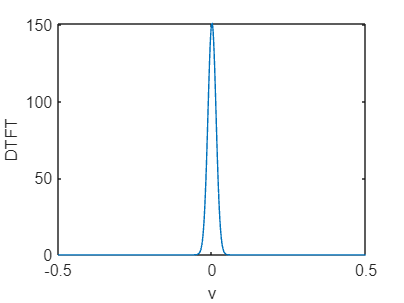

G_DTFT = v*0; % initialize vector G_DTFT with the same number of points of v
for u = 1:length(v)
G_DTFT(u) = sum(g.*exp(-1i*2*pi*v(u)*n));
end
figure(1)
plot(v,abs(G_DTFT)) % plot the DTFT.
xlabel('v')
ylabel('DTFT')

fs = 1/Ts;
f = v*fs;

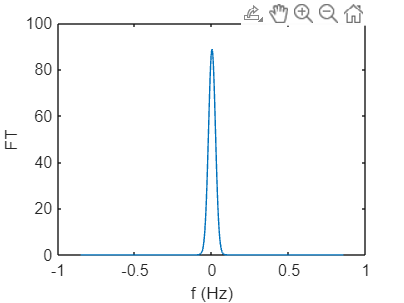

G_FT = G_DTFT./fs; % create a vector storing samples of the Fourier transform
plot(f,abs(G_FT)) % plot the FT
xlabel('f (Hz)')
ylabel('FT')